# Projetos via realimentação de estados

**Sistema realimentados**

Seja o sistema dado por:


$$\dot{x}=Ax+Bu$$



$$y=Cx$$



$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-10 & -17 & -8
\end{array}\right\rbrack$$
  
$$B=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$
 
$$C=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$
 
$$D=0$$


A=[0 1 0;0 0 1;-10 -17 -8];
B=[0;0;10];
C=[1 0 0];
D=0;
s1=ss(A,B,C,D)


s1 =
 
  A = 
        x1   x2   x3
   x1    0    1    0
   x2    0    0    1
   x3  -10  -17   -8
 
  B = 
       u1
   x1   0
   x2   0
   x3  10
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



g1=tf(s1)


g1 =
 
            10
  -----------------------
  s^3 + 8 s^2 + 17 s + 10
 
Continuous-time transfer function.



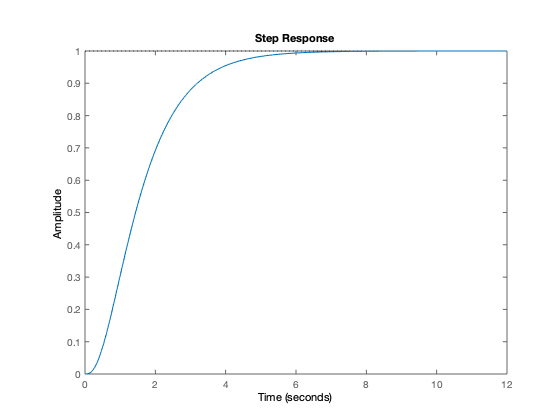

figure;
step(g1);

**Realimentação de estados**

Como o sistema responde em 6 segundos, escolheremos tempo de estabilização Ts=2s e UP=4.3%.

UP=4.3;
Ts=2;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2))

zeta = 0.7077

wn=4/(Ts*zeta)

wn = 2.8262

polos=roots([1 2*zeta*wn wn^2])

polos =   -2.0000 + 1.9968i
  -2.0000 - 1.9968i


Escolha localizações para p3

p3=-5;
polos=[polos; p3]

polos =   -2.0000 + 1.9968i
  -2.0000 - 1.9968i
  -5.0000 + 0.0000i


**Realimentação de estados**

K=place(A,B,polos)

K =     2.9937    1.0987    0.1000


**Sistema em malha fechada**

s1mf=ss(A-B*K,B,C,D)


s1mf =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3  -39.94  -27.99      -9
 
  B = 
       u1
   x1   0
   x2   0
   x3  10
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**Função de transferência de malha fechada**

g1mf=tf(s1mf)


g1mf =
 
               10
  -----------------------------
  s^3 + 9 s^2 + 27.99 s + 39.94
 
Continuous-time transfer function.



**Simulação ao degrau em malha fechada**

Confira o atendimento da especificação feita

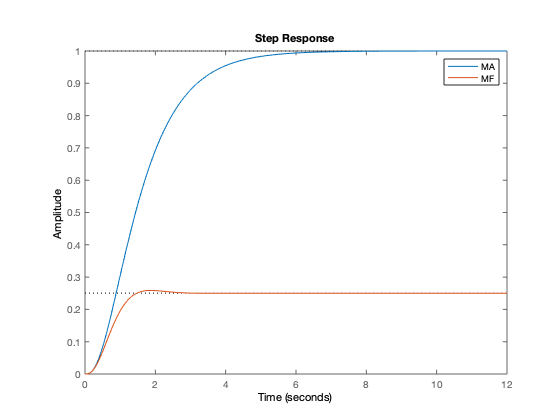

figure;
step(s1,s1mf);legend('MA','MF');

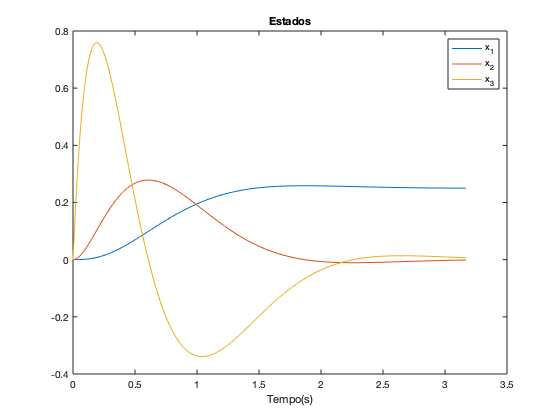

[y,t,x]=step(s1mf); % Gera os estados
u=1-K*(x'); % Calcula o sinal de controle
figure;
plot(t,x);legend('x_1','x_2','x_3');
title('Estados');xlabel('Tempo(s)');

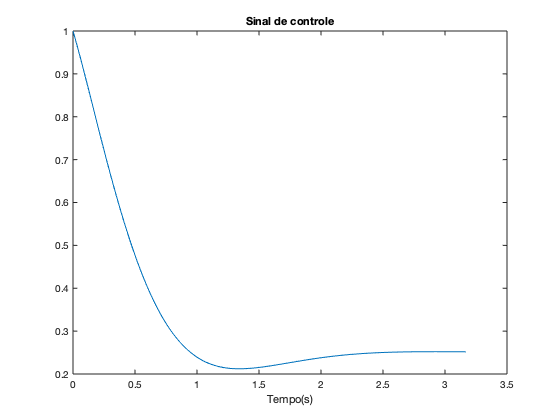

figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

**Realimentação integral de estados**

O integrador (polo na origem) no sinal de erro garante que a saída y tenda para a referência se o sistema for estável, ou seja, todos os polos estão no SPE. Tem-se, portanto, um sistema tipo1, com a FT  $\frac{k_4}{s}C(sI-A+BK)^{-1}B$,  sendo $K=\left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack$.

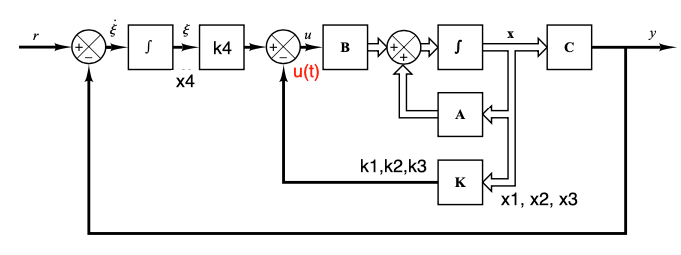

Usando os dados anteriores, constroi-se o sistema aumentado, ou seja, com um estado adicional devido ao polo na origem. Agora o sistema terá 4 estados. 

A1=[A [0;0;0];[-C 0]]

A1 =      0     1     0     0
     0     0     1     0
   -10   -17    -8     0
    -1     0     0     0


B1=[B;0];
Br=[0 ;0;0;1]; % Br é diferente de B1, ver notas de aula
C1=[C 0];
D1=D;


Altere a localização de p4 e observe o efeito na resposta y(t)=x1(t) e no sinal de controle u(t)

p4=-10;
polos4=[polos;p4 ];
K1=place(A1,B1,polos4)

K1 =    30.9811   10.0987    1.1000  -39.9370


**Sistema em malha fechada**

simf=ss(A1-B1*K1,Br,C1,D1)


simf =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0       1       0
   x3  -319.8    -118     -19   399.4
   x4      -1       0       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



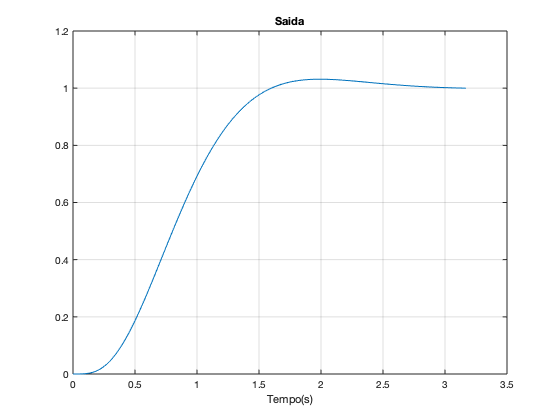

[y,t,x]=step(simf);
u=-K1*(x');
figure;plot(t,y);grid;
title('Saida');xlabel('Tempo(s)');

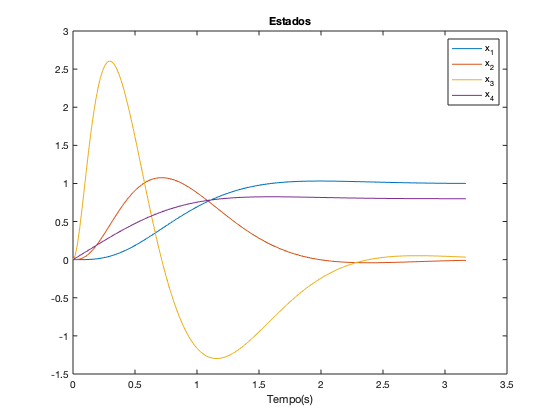

figure;
plot(t,x);legend('x_1','x_2','x_3','x_4');
title('Estados');xlabel('Tempo(s)');

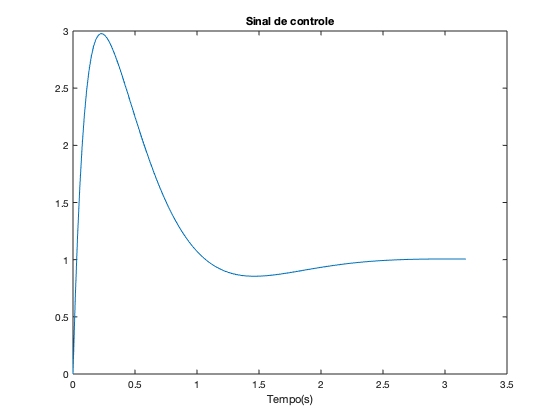

figure;
plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');